
    % Detect on the Conveyer to see if blocks exist, return the centroids
    clc;
    
    CameraCalibrationConveyor;


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 1302.8951 +/- 2.7291     1306.9516 +/- 2.8776  ]
Principal point (pixels):[  787.1206 +/- 1.4808      564.9115 +/- 1.3826  ]
Radial distortion:       [    0.0724 +/- 0.0052       -0.2211 +/- 0.0200  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0460 +/- 0.0022        0.0014 +/- 0.0022        1.6050 +/- 0.0003  ]
                         [    0.0247 +/- 0.0023       -0.0417 +/- 0.0025        1.6247 +/- 0.0003  ]
                         [    0.4143 +/- 0.0017       -0.4880 +/- 0.0015        1.3977 +/- 0.0004  ]
                         [    0.5950 +/- 0.0017        0.5495 +/- 0.0018        1.3552 +/- 0.0005  ]
                         [   -0.3179 +/- 0.0015        0.5712 +/- 0.0017        1.4968 +/- 0.0004  ]
                         [    0.4997 +/- 0.0014       -0.4725 +/- 0.0014        1.4268 +/- 0.0005  ]
 

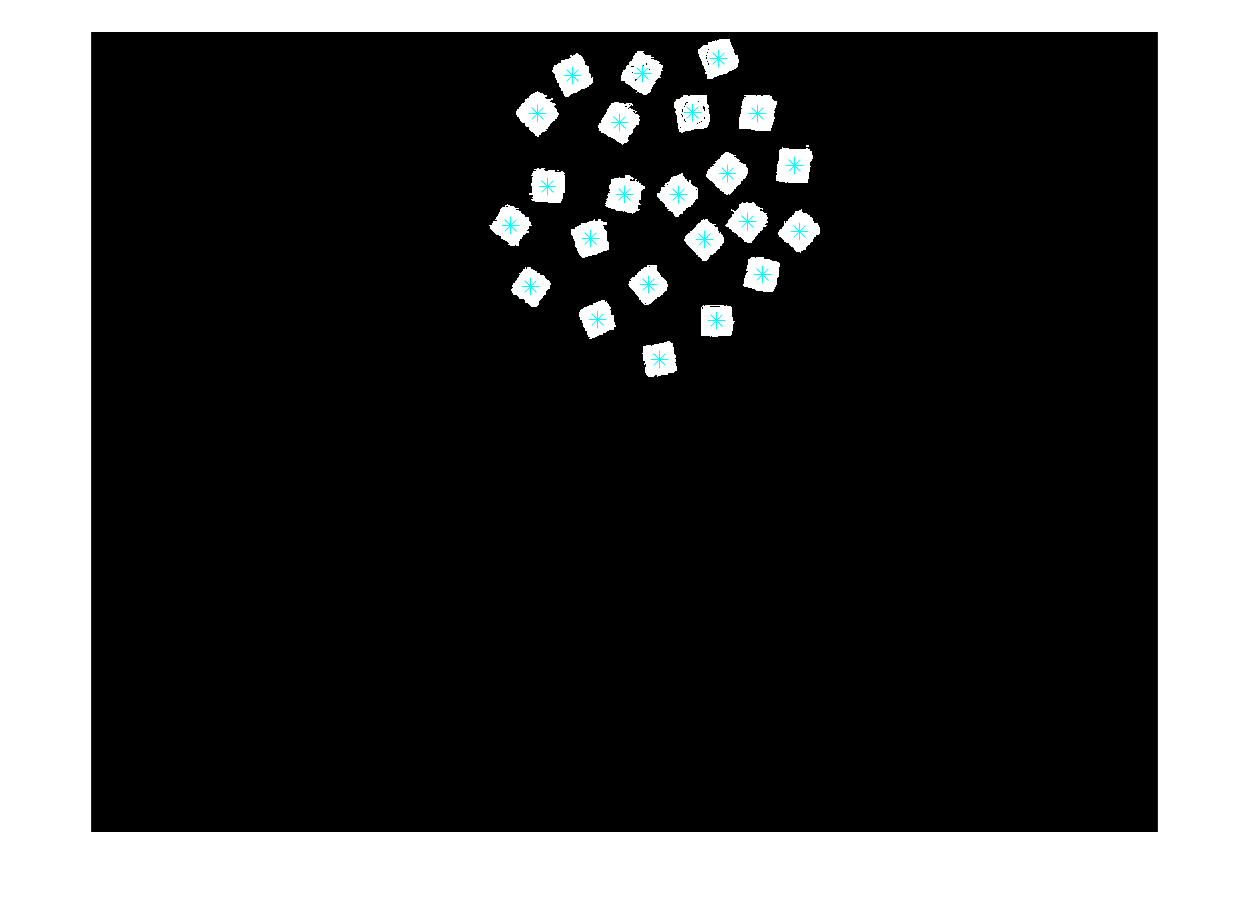

    conveyorImg = imread('Proper_Pics\conveyor6.jpg');
    conveyorImg = undistortImage(conveyorImg,cameraParamsConveyor);
    %figure(); imshow(conveyorImg);

    [BW,maskedRGBImage] = createConveyorMask2(conveyorImg);
    BW = ~BW;
    BW = segmentSection(BW, 560, 1155, 10, 586);
    BW = bwareaopen(BW,2000);             % remove white noise
    BW = bwmorph(BW, 'hbreak');

    % use regionprops to calculate centroids
    blockProps = regionprops(BW, 'Centroid','Area');
    centroids = vertcat(blockProps.Centroid);
    areas = vertcat(blockProps.Area);
    if size(centroids,1) > 0
        removeIdx = find(areas > 7000 | areas < 1000);
        areas(removeIdx) = [];
        centroids(removeIdx,:) = [];
        % convert to real life
        conveyorList = conveyorPxlToReal(centroids(:,1), centroids(:,2));  
        conveyorList = [conveyorList zeros(size(conveyorList,1),1)];
        figure();
        imshow(BW); hold on;
        plot(centroids(:,1), centroids(:,2), 'c*', 'MarkerSize', 10);
    else
        display("No blocks detected on the conveyor");
        conveyorList = [];
    end